## Generate all the IDP and PLV Value's

PatientIDs = {'P1','P2','P3'}; 

GenerateIPD_PLVTables(PatientIDs); 

  Columns 1 through 11

    {'Fz-FC3'}    {'Fz-FC1'}    {'Fz-FCz'}    {'Fz-FC2'}    {'Fz-FC4'}    {'Fz-C3'}    {'Fz-C1'}    {'Fz-C2'}    {'Fz-C4'}    {'Fz-CP3'}    {'Fz-CP1'}

  Columns 12 through 21

    {'Fz-CPz'}    {'Fz-CP2'}    {'Fz-CP4'}    {'FC3-FC1'}    {'FC3-FCz'}    {'FC3-FC2'}    {'FC3-FC4'}    {'FC3-C3'}    {'FC3-C1'}    {'FC3-C2'}

  Columns 22 through 31

    {'FC3-C4'}    {'FC3-CP3'}    {'FC3-CP1'}    {'FC3-CPz'}    {'FC3-CP2'}    {'FC3-CP4'}    {'FC1-FCz'}    {'FC1-FC2'}    {'FC1-FC4'}    {'FC1-C3'}

  Columns 32 through 41

    {'FC1-C1'}    {'FC1-C2'}    {'FC1-C4'}    {'FC1-CP3'}    {'FC1-CP1'}    {'FC1-CPz'}    {'FC1-CP2'}    {'FC1-CP4'}    {'FCz-FC2'}    {'FCz-FC4'}

  Columns 42 through 51

    {'FCz-C3'}    {'FCz-C1'}    {'FCz-C2'}    {'FCz-C4'}    {'FCz-CP3'}    {'FCz-CP1'}    {'FCz-CPz'}    {'FCz-CP2'}    {'FCz-CP4'}    {'FC2-FC4'}

  Columns 52 through 61

    {'FC2-C3'}    {'FC2-C1'}    {'FC2-C2'}    {'FC2-C4'}    {'FC2-CP3'}    {'FC2-CP1'}    {'FC2-CPz'}    {

## Table Generation of Required Patient 

PatientID = "P3";
if ispc
        % For Windows
        % Construct the file path using sprintf
        IPDTable = load(sprintf('..\\OwnResults\\%sRH\\MatlabGeneratedData\\IPDTable.mat', PatientID)).IPDTable;
        PLVTable = load(sprintf('..\\OwnResults\\%sRH\\MatlabGeneratedData\\PLVTable.mat', PatientID)).PLVTable;
        IPD_PLVTable = load(sprintf('..\\OwnResults\\%sRH\\MatlabGeneratedData\\IPD_PLVTable.mat', PatientID)).IPD_PLVTable;
    elseif ismac
        IPDTable = load(sprintf('../OwnResults/%sRH/MatlabGeneratedData/IPDTable.mat', PatientID)).IPDTable;
        PLVTable = load(sprintf('../OwnResults/%sRH/MatlabGeneratedData/PLVTable.mat', PatientID)).PLVTable;
        IPD_PLVTable = load(sprintf('../OwnResults/%sRH/MatlabGeneratedData/IPD_PLVTable.mat', PatientID)).IPD_PLVTable;
end

## ANOVA

## ANOVA one way but determining the best number of features for highest accuracy

   200     1



|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        Delta |        Gamma |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |       0.475 |    0.034818 |       0.475 |       0.475 |      0.41209 |      0.34362 |
|    2 | Best   |        0.38 |     0.03273 |        0.38 |     0.38627 |      0.38417 |      0.98128 |
|    3 | Accept |         0.5 |    0.036432 |        0.38 |     0.38003 |      0.91482 |      0.63152 |
|    4 | Accept |         0.5 |    0.039037 |        0.38 |     0.38001 |      0.92798 |      0.20919 |
|    5 | Best   |       0.365 |    0.033284 |       0.365 |       0.365 |      0.37449 |      0.38119 |
|    6 | Best   |       0.325 |    0.039494 |       0.325 |     

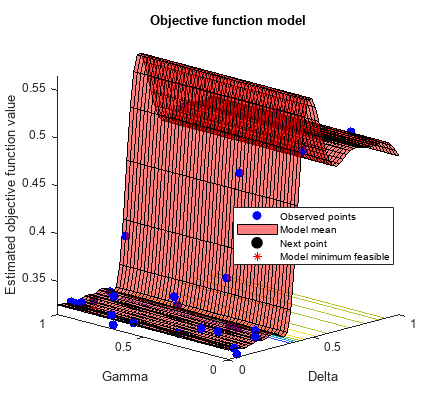

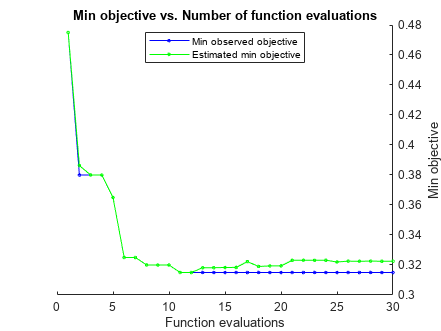


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 11.3886 seconds
Total objective function evaluation time: 0.98159

Best observed feasible point:
     Delta       Gamma  
    ________    ________

    0.090559    0.038788

Observed objective function value = 0.315
Estimated objective function value = 0.32255
Function evaluation time = 0.034568

Best estimated feasible point (according to models):
     Delta       Gamma  
    ________    ________

    0.090559    0.038788

Estimated objective function value = 0.32255
Estimated function evaluation time = 0.032645



ChosenTable = IPDTable; 

columnNames = ChosenTable.Properties.VariableNames;
predictorNames = columnNames(1,1:end-1);
isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];


predictors = ChosenTable(:, predictorNames);
response = ChosenTable.Class;

predictors = standardizeMissing(predictors, {Inf, -Inf});
predictorMatrix = normalize(predictors);
newPredictorMatrix = zeros(size(predictorMatrix));
for i = 1:size(predictorMatrix, 2)
    if isCategoricalPredictor(i)
        newPredictorMatrix(:,i) = grp2idx(predictorMatrix{:,i});
    else
        newPredictorMatrix(:,i) = predictorMatrix{:,i};
    end
end
predictorMatrix = newPredictorMatrix;
responseVector = grp2idx(response);

% Rank features using ANOVA algorithm
for i = 1:size(predictorMatrix, 2)
    pValues(i) = anova1(...
        predictorMatrix(:,i), ...
        responseVector, ...
        'off');
end
[~,featureIndex] = sort(-log(pValues), 'descend');


%Generating the plot to determine the best number of features
accuracies = [];
numberofFeatures = []; 
stepsize = 10; 

for i = 1:stepsize:1
    includedPredictorNames = predictors.Properties.VariableNames(featureIndex(1:i));
    iterationspredictors = predictors(:,includedPredictorNames);
    numberofFeatures = [numberofFeatures, i]; 
    
    %Determine which iteration it is at 
    disp(size(iterationspredictors));

    % Define the LDA model function for Bayesian Optimization
    ldaModel = @(params)fitcdiscr(iterationspredictors, response, ...
        'Delta', params.Delta, ...
        'Gamma', params.Gamma, ...
        'CrossVal', 'on', ...
        'KFold', 10);
    
    % Define the optimization variables
    optimVars = [
        optimizableVariable('Delta', [0, 1]), ... % Range for Delta
        optimizableVariable('Gamma', [0, 1])  ... % Range for Gamma
        ];
    
    % Define the objective function for Bayesian optimization
    minfn = @(params)kfoldLoss(ldaModel(params));
    
    % Run Bayesian Optimization
    results = bayesopt(minfn, optimVars, ...
        'MaxObjectiveEvaluations', 30, ...
        'Verbose', 1, ...
        'IsObjectiveDeterministic', false, ...
        'AcquisitionFunctionName', 'expected-improvement-plus');
    
    % Extract the best hyperparameters
    bestParams = bestPoint(results);

    numFolds = 10; % Number of folds for cross-validation
    rng(1); % Fixed seed for consistent results
    
    % Use the full combined table for cross-validation
    xtrain = iterationspredictors;
    ytrain = response;
    cvPartition = cvpartition(ytrain, 'KFold', numFolds, 'Stratify', true);
    
    
    foldAccuracy = zeros(numFolds, 1);
    
    for fold = 1:numFolds
        trainIndices = cvPartition.training(fold);
        testIndices = cvPartition.test(fold);
    
        XtrainFold = xtrain(trainIndices, :);
        YtrainFold = ytrain(trainIndices);
        XtestFold = xtrain(testIndices, :);
        YtestFold = ytrain(testIndices);

        LDAModel = fitcdiscr(iterationspredictors, response, ...
        'Delta', bestParams.Delta, ...
        'Gamma', bestParams.Gamma);
    
        YtestPred = predict(LDAModel, XtestFold);
    
        foldAccuracy(fold) = sum(YtestPred == YtestFold) / length(YtestFold);
    end

        accuracies = [accuracies, mean(foldAccuracy)];
end 

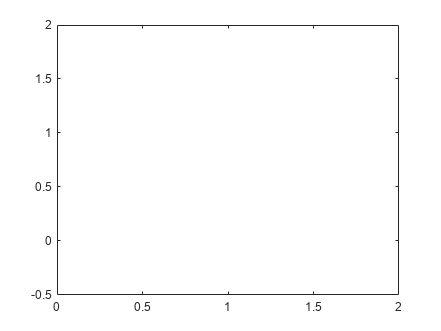

plot(numberofFeatures,accuracies)

numFeaturesToKeep = 50;
includedPredictorNames = predictors.Properties.VariableNames(featureIndex(1:numFeaturesToKeep));
predictors = predictors(:,includedPredictorNames);

## Simple LDA Classification of Combined Table

% Extract features and labels
predictor = IPD_PLVTable{:, 1:end-1};  % Features
response = IPD_PLVTable.Class;         % Labels

% Split the data into a training set and a test set (75% training, 25% test)
cv = cvpartition(response, 'HoldOut', 0.25);
predictor_train = predictor(training(cv), :);
response_train = response(training(cv), :);
predictor_test = predictor(test(cv), :);
response_test = response(test(cv), :);

% Train the LDA model on the training set
finalLDAModel = fitcdiscr(predictor_train, response_train);

% Predict labels on the training data
trainPredictedLabels = predict(finalLDAModel, predictor_train);

% Predict labels on the test data
testPredictedLabels = predict(finalLDAModel, predictor_test);

% Calculate the training accuracy
trainAccuracy = sum(trainPredictedLabels == response_train) / length(response_train) * 100;

% Calculate the test accuracy
testAccuracy = sum(testPredictedLabels == response_test) / length(response_test) * 100;

% Display the training and test accuracy
fprintf('Final LDA model training accuracy: %.2f%%\n', trainAccuracy);

Final LDA model training accuracy: 100.00%


fprintf('Final LDA model test accuracy: %.2f%%\n', testAccuracy);

Final LDA model test accuracy: 70.00%


## Hyperparameter tuning

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        Delta |        Gamma |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |       0.475 |    0.043194 |       0.475 |       0.475 |      0.41209 |      0.34362 |
|    2 | Best   |        0.38 |     0.03022 |        0.38 |     0.38627 |      0.38417 |      0.98128 |
|    3 | Accept |         0.5 |    0.036518 |        0.38 |     0.38003 |      0.91482 |      0.63152 |
|    4 | Accept |         0.5 |    0.030701 |        0.38 |     0.38001 |      0.92798 |      0.20919 |
|    5 | Best   |       0.365 |    0.032141 |       0.365 |       0.365 |      0.37449 |      0.38119 |
|    6 | Best   |       0.325 |    0.031513 |       0.325 |     


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 11.2531 seconds
Total objective function evaluation time: 0.98344

Best observed feasible point:
     Delta       Gamma  
    ________    ________

    0.090559    0.038788

Observed objective function value = 0.315
Estimated objective function value = 0.32255
Function evaluation time = 0.033038

Best estimated feasible point (according to models):
     Delta       Gamma  
    ________    ________

    0.090559    0.038788

Estimated objective function value = 0.32255
Estimated function evaluation time = 0.032649



% Define the LDA model function for Bayesian Optimization
    ldaModel = @(params)fitcdiscr(iterationspredictors, response, ...
        'Delta', params.Delta, ...
        'Gamma', params.Gamma, ...
        'CrossVal', 'on', ...
        'KFold', 10);
    
    % Define the optimization variables
    optimVars = [
        optimizableVariable('Delta', [0, 1]), ... % Range for Delta
        optimizableVariable('Gamma', [0, 1])  ... % Range for Gamma
        ];
    
    % Define the objective function for Bayesian optimization
    minfn = @(params)kfoldLoss(ldaModel(params));
    
    % Run Bayesian Optimization
    results = bayesopt(minfn, optimVars, ...
        'MaxObjectiveEvaluations', 30, ...
        'Verbose', 1, ...
        'IsObjectiveDeterministic', false, ...
        'AcquisitionFunctionName', 'expected-improvement-plus');

    
    % Extract the best hyperparameters
    bestParams = bestPoint(results);

## Stratified K-Fold Cross-Validation of Combined Table

% Define the number of folds for cross-validation
numFolds = 10; % Number of folds for cross-validation
rng(1); % Fixed seed for consistent results

% Use the full combined table for cross-validation
xtrain = predictor;
ytrain = response;

% Create a stratified partition object
cvPartition = cvpartition(ytrain, 'KFold', numFolds, 'Stratify', true);

% Initialize array to hold accuracy for each fold
foldAccuracy = zeros(numFolds, 1);

% Perform stratified cross-validation
for fold = 1:numFolds
    % Extract the training and test sets for the current fold
    trainIndices = cvPartition.training(fold);
    testIndices = cvPartition.test(fold);

    XtrainFold = xtrain(trainIndices, :);
    YtrainFold = ytrain(trainIndices);
    XtestFold = xtrain(testIndices, :);
    YtestFold = ytrain(testIndices);

    % Train the LDA model on the training set of the current fold
    LDAModel = fitcdiscr(XtrainFold, YtrainFold, ...
    'Delta', bestParams.Delta, ...
    'Gamma', bestParams.Gamma);

    % Predict labels on the test data for the current fold
    YtestPred = predict(LDAModel, XtestFold);

    % Calculate the accuracy for the current fold
    foldAccuracy(fold) = sum(YtestPred == YtestFold) / length(YtestFold);
end

% Calculate the average accuracy across all folds
meanAccuracy = mean(foldAccuracy);

% Display the average cross-validation accuracy
disp(['Average Cross-Validation Accuracy: ', num2str(meanAccuracy * 100), '%']);

Average Cross-Validation Accuracy: 52.5%
